# Cours 19.10.22

## Exemple. trouverles zéros de la f(x) = 3*x + sin(x) - exp(x)

Par méthode Newton

f = @(x) 3*x+sin(x)-exp(x)

f = function_handle with value:
    @(x)3*x+sin(x)-exp(x)

fp = @(x) 3+cos(x)-exp(x) % dérivée de f

fp = function_handle with value:
    @(x)3+cos(x)-exp(x)


newton(f, fp, 0, 1e-5)

ans = 0.3604

f(ans)

ans = -6.6613e-16

newton(f, fp, 2, 1e-5)

ans = 1.8900

f(ans)

ans = 0

## Exemple : Le point de départ doit bien être défini. Ici, il ne fonctionne pas en 0

f = @(x) x^2 - 2

f = function_handle with value:
    @(x)x^2-2

fp = @(x) 2*x

fp = function_handle with value:
    @(x)2*x

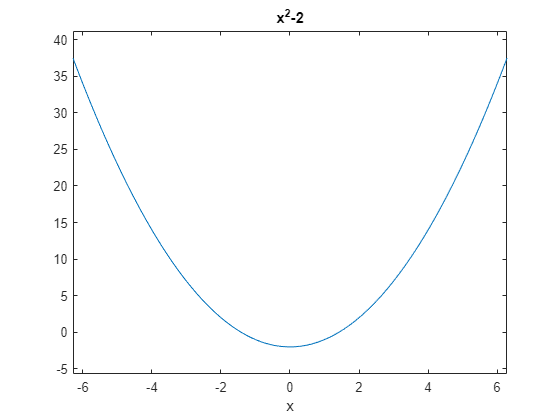

ezplot(f)

newton(f, fp, 0, 1e-5) % Ne fonctionne pas

ans = Inf


newton(f, fp, 2, 1e-5) % Fonctionne

ans = 1.4142

f(ans)

ans = 4.5106e-12

## Avantages et Inconvénients

+ Utilise peu d'itérations, très rapide

+ Fonctionne pour fonctions a plusieurs variables

- Calcul de la dérivée nécessaire

- Peu ne pas fonctionner (boucle, départ mal déterminé)

[s n] = newton(f, fp, 2, 1e-5) % Uniquement 4 itérations

s = 1.4142

n = 4

[s n] = newton(f, fp, 5, 1e-5) % 6

s = 1.4142

n = 6

[s n] = newton(f, fp, 500, 1e-5) % 13

s = 1.4142

n = 13



f = @(x) 3*x+sin(x)-exp(x)

f = function_handle with value:
    @(x)3*x+sin(x)-exp(x)

fp = @(x) 3+cos(x)-exp(x)

fp = function_handle with value:
    @(x)3+cos(x)-exp(x)

[s n] = newton(f, fp, 0, 1e-5) % 4

s = 0.3604

n = 4

[s n] = newton(f, fp, 2, 1e-5) % 4

s = 1.8900

n = 4


% 4 à 6 itérations ici
f = @(x) sin(x)

f = function_handle with value:
    @(x)sin(x)

fp = @(x) cos(x)

fp = function_handle with value:
    @(x)cos(x)

[s n] = newton(f, fp, 0.5, 1e-5)

s = 0

n = 5

[s n] = newton(f, fp, 0.3, 1e-5)

s = 0

n = 5

[s n] = newton(f, fp, 0.2, 1e-5)

s = 0

n = 4

[s n] = newton(f, fp, 1, 1e-5)

s = 0

n = 6

% Alors que pour la bissection : plus de 550
[s n] = bissection(-1, 1, 1e-5, f) % 556

s = -1.5281e-162

n = 556

## Méthode de la sécante


f = @(x) 3*x+sin(x)-exp(x)

f = function_handle with value:
    @(x)3*x+sin(x)-exp(x)


[s n] = secante(1, 2, 1e-5, f) % 6 itérations

s = 1.8900

n = 6

f(s)

ans = -1.3819e-10

[s n] = secante(0, 2, 1e-5, f)

s = 1.8900

n = 7

f(s)

ans = -1.5439e-09

[s n] = secante(0, 10, 1e-5, f)

s = 0.3604

n = 7

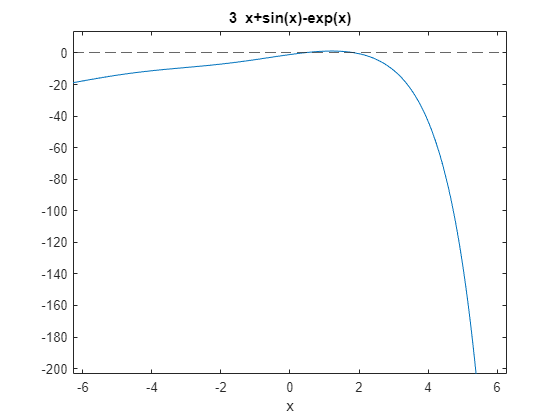


ezplot(f)
yline(0, '--')

[s n] = secante(-2, -3, 1e-5, f)

s = 0.3604

n = 9

## Résolution de système à plusieurs variables (ou implicites)

% fonctions de plusieurs variables
% Nous avons deux équations implicites et on aimerait résoudre le système.
% On mets tous les termes pour avoir chaque équation = 0
% On définit chacune par un nom de fonction. Ici f et g
% On cherche a résoudre à la fois f=0 et g=0
f = @(x, y) 2*x - y - exp(-x)

f = function_handle with value:
    @(x,y)2*x-y-exp(-x)

g = @(x, y) 2*y - x - exp(-y)

g = function_handle with value:
    @(x,y)2*y-x-exp(-y)


f(2, 1)

ans = 2.8647

f(2, 3)

ans = 0.8647

f(2, 4)

ans = -0.1353

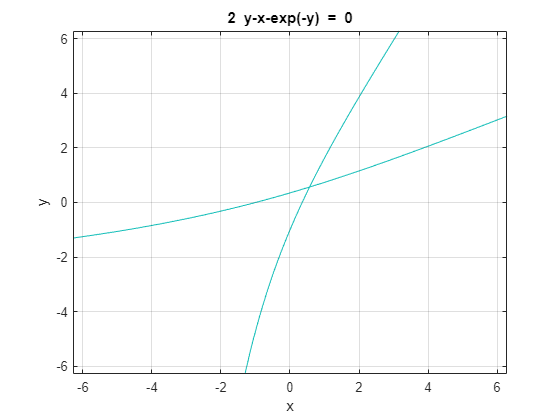


% Courbe de niveau 0 (f = 0) :
ezplot(f); hold on;
ezplot(g);

% L'intersection des deux nous donne le point pour f=0 et g=0

% Pour résoudre on utilise la fonction fsolve de Matlab. Cependant elle
% requiert une fonction créée pour un cas spécifique. Dans notre cas la
% fonction exemple. Dedans sont définies les fonctions à résoudre.
exemple([0, 0])

ans =     -1    -1


exemple([0.55, 0.6])

ans =    -0.0769    0.1012


XY = fsolve(@exemple, [0, 0]) % Retour : Point (x, y) solution


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


XY =     0.5671    0.5671


exemple(XY)

ans = 1.0e-06 *

   -0.1965   -0.1965
